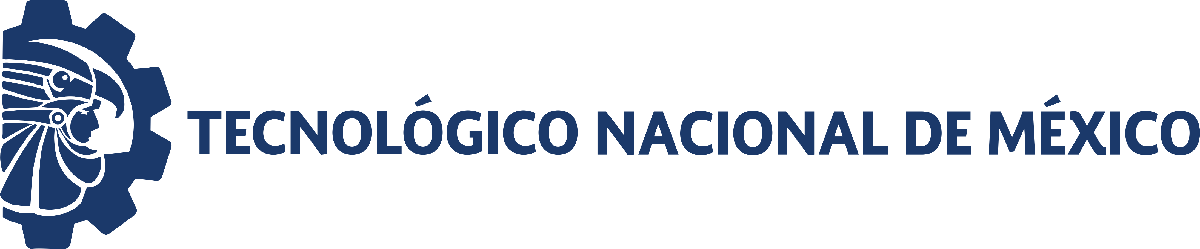                                 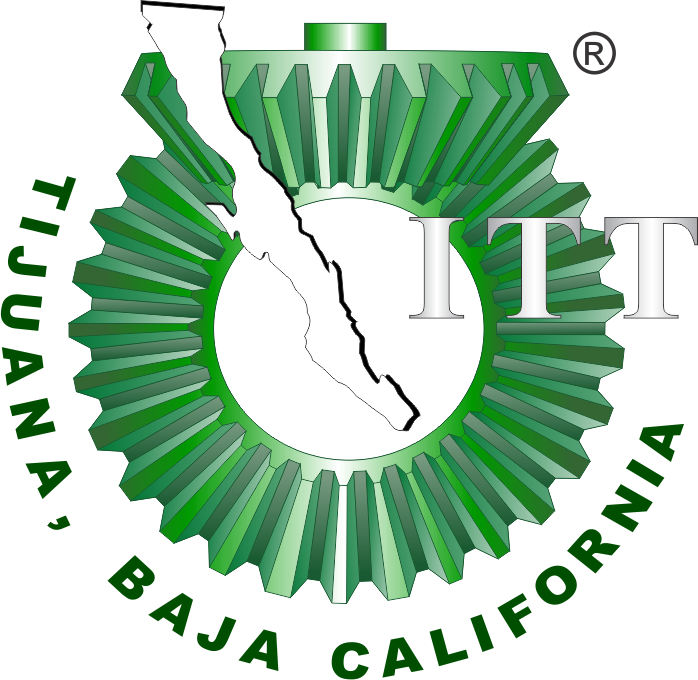

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

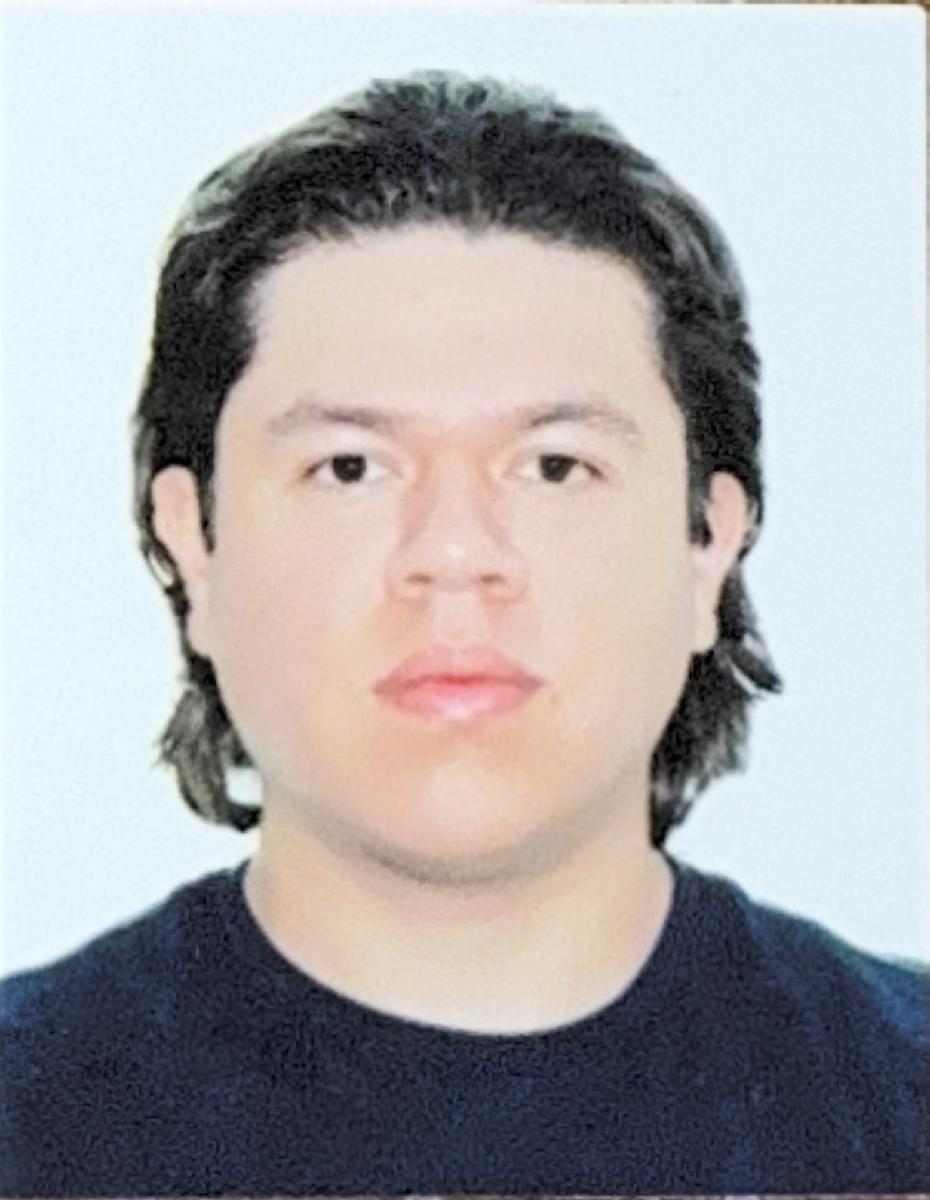

Nombre del alumno: Carlos Azael Ramirez Rodriguez

Número de control: 22212267

Correo institucional: L22212267**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaB'

file = 'SistemaB'

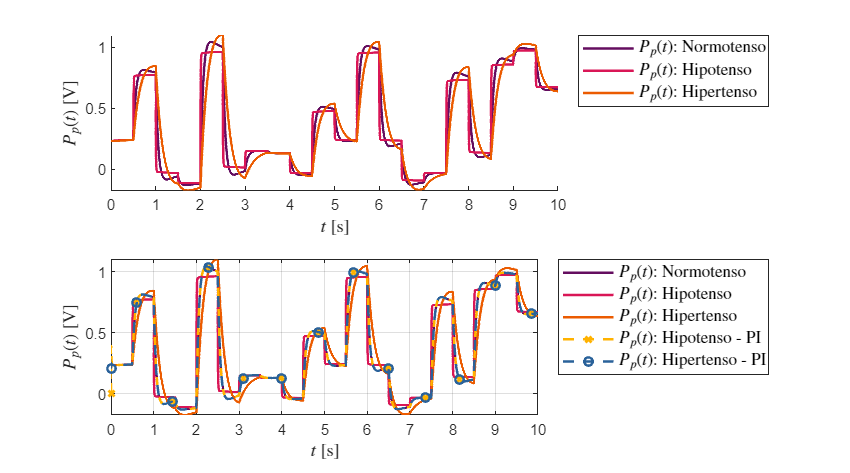

open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'VariableStepAuto';
parameters.MaxStep = '1E-3';
set_param('SistemaB/Ppa(t)','Minimum','-0.2');
set_param('SistemaB/Ppa(t)','Maximum','1');
set_param('SistemaB/Ppa(t)','Seed','106');
set_param('SistemaB/Ppa(t)','SampleTime','0.5');
Signal = 'sistema cardiovascular';
x = sim(file, parameters);
writematrix(x.Ppa,'signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,Signal) 

## Función: Respuesta a las señales

function plotsignals(t, Pp0, Pp1, Pp2, Pp3, Pp4, Signal)
    % === CONFIGURACIÓN DE FIGURA ===
    fig = figure('Color', 'w');
    set(fig, 'Units', 'centimeters', 'Position', [1, 1, 18, 10]);

    % Colores personalizados
    mycolors = [100,13,95;
                217,22,86;
                235,91,0;
                255,178,0;
                42,98,154;
                247,82,112]/255;

    colororder(mycolors);

    % === SUBPLOT 1: sin PI ===
    subplot(2,1,1);
    hold on;
    plot(t, Pp0, '-', 'LineWidth', 1.5);
    plot(t, Pp1, '-', 'LineWidth', 1.5);
    plot(t, Pp2, '-', 'LineWidth', 1.5);
    legend({'$P_{p}(t)$: Normotenso', ...
            '$P_{p}(t)$: Hipotenso', ...
            '$P_{p}(t)$: Hipertenso'}, ...
            'Interpreter', 'latex', 'FontSize', 10, 'Location', 'bestoutside', 'Box', 'on');
    xlabel('$t$ [s]', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('$P_p(t)$ [V]', 'Interpreter', 'latex', 'FontSize', 11);
    xlim([0,10]); xticks(0:1:10);

    % === SUBPLOT 2: con PI ===
    subplot(2,1,2);
    hold on; box on; grid on;
    plot(t, Pp0, '-', 'LineWidth', 1.5);
    plot(t, Pp1, '-', 'LineWidth', 1.5);
    plot(t, Pp2, '-', 'LineWidth', 1.5);
    plot(t, Pp3, '--x','LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    plot(t, Pp4, '--o','LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    legend({'$P_{p}(t)$: Normotenso', ...
            '$P_{p}(t)$: Hipotenso', ...
            '$P_{p}(t)$: Hipertenso', ...
            '$P_{p}(t)$: Hipotenso - PI', ...
            '$P_{p}(t)$: Hipertenso - PI'}, ...
            'Interpreter', 'latex', 'FontSize', 10, 'Location', 'bestoutside', 'Box', 'on');
    xlabel('$t$ [s]', 'Interpreter', 'latex', 'FontSize', 11);
    ylabel('$P_p(t)$ [V]', 'Interpreter', 'latex', 'FontSize', 11);
    xlim([0,10]); xticks(0:1:10);

    % === EXPORTAR FIGURA ===
    exportgraphics(fig, [Signal, '.pdf'], 'ContentType', 'vector');
    exportgraphics(fig, [Signal, '.png'], 'ContentType', 'vector');
end


